# Hippocampus 

subject ='Group';
plot_window=[1 25 1920 1080];
home_dir = '/bigvault/Projects/seeg_pointing';
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';

% obj_pic = 51:165; % original [-2,3], save [-0.5,1.5], pic [0,1.15]
% seq_pic = 251:500;% original [-5,7], save [-2.5,5], pic [0,2.5]
% seq_pre = 1:200;  % original [-5,7], save [-2.5,5], pre interval [-2.5,-0.5]
% seq_after = 501:700;% original [-5,7], save [-2.5,5], pre interval [2.5,4.5]

index = [7,13,25,31,43,49];
bd_id = [index,index+18*6]; 
non_bd_id = [index+18*3,index+18*9]; 

% load wavlet data for subject
data_bd = load_mat([group_dir,'wavelet/wavele_bd.mat']);
data_non_bd = load_mat([group_dir,'wavelet/wavele_non_bd.mat']);

% condition
temp = squeeze(mean(data_bd(:,:,:,:),1));
bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd(:,:,:,:),1)); 
non_bd = permute(temp,[2,3,1]);

% position
temp = squeeze(mean(data_bd([7,13],:,:,:),1));
wavelet_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_bd([6,12],:,:,:),1)); 
wavelet_pre_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([7,13],:,:,:),1)); 
wavelet_non_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([6,12],:,:,:),1)); 
wavelet_pre_non_bd = permute(temp,[2,3,1]);

### Boundary turns vs nonBoundary turns

#### total

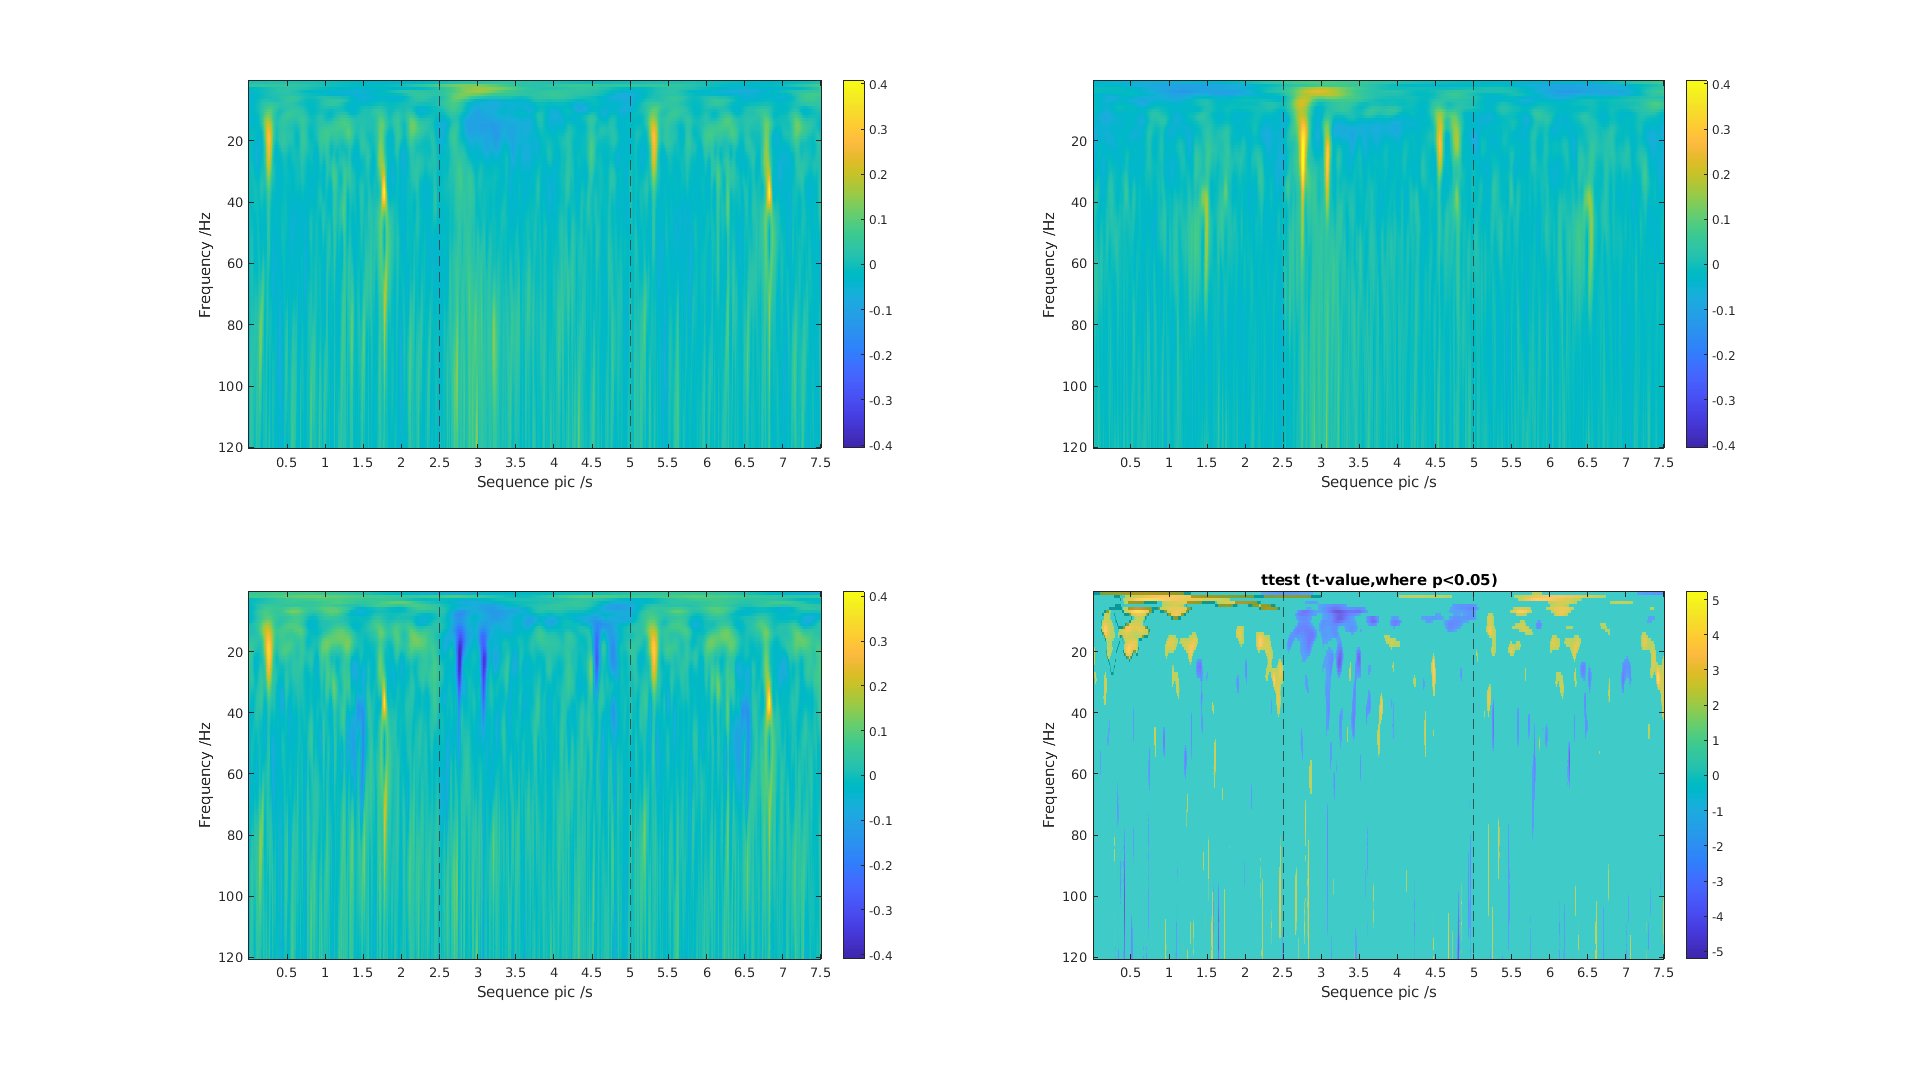

cp = 1×166 cell array
    {9289×1 double}    {2930×1 double}    {2400×1 double}    {2354×1 double}    {2000×1 double}    {1797×1 double}    {1513×1 double}    {1181×1 double}    {602×1 double}    {537×1 double}    {476×1 double}    {542×1 double}    {452×1 double}    {517×1 double}    {367×1 double}    {456×1 double}    {422×1 double}    {387×1 double}    {415×1 double}    {365×1 double}    {310×1 double}    {339×1 double}    {282×1 double}    {298×1 double}    {332×1 double}    {270×1 double}    {247×1 double}    {256×1 double}    {251×1 double}    {227×1 double}    {227×1 double}    {239×1 double}    {236×1 double}    {222×1 double}    {214×1 double}    {166×1 double}    {191×1 double}    {184×1 double}    {178×1 double}    {210×1 double}    {174×1 double}    {171×1 double}    {158×1 double}    {159×1 double}    {160×1 double}    {167×1 double}    {136×1 double}    {137×1 double}    {141×1 double}    {144×1 double}    {149×1 double}    {138×1 double}    {135×1 double}    {108×1 doubl

pp =     0.0027    0.0819    0.1356    0.1600    0.2063    0.2788    0.3354    0.5027    0.8227    0.8887    0.8903    0.8906    0.9019    0.9036    0.9298    0.9365    0.9375    0.9430    0.9430    0.9778    0.9857    0.9867    0.9895    0.9915    0.9918    0.9936    0.9956    0.9965    0.9968    0.9977    0.9978    0.9988    0.9989    0.9989    0.9991    0.9991    0.9992    0.9992    0.9992    0.9992    0.9998    0.9998    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    1.0000


[cp, pp, ~, ~]= plt_rsa_sd_perm(bd,non_bd,'wavelet') 

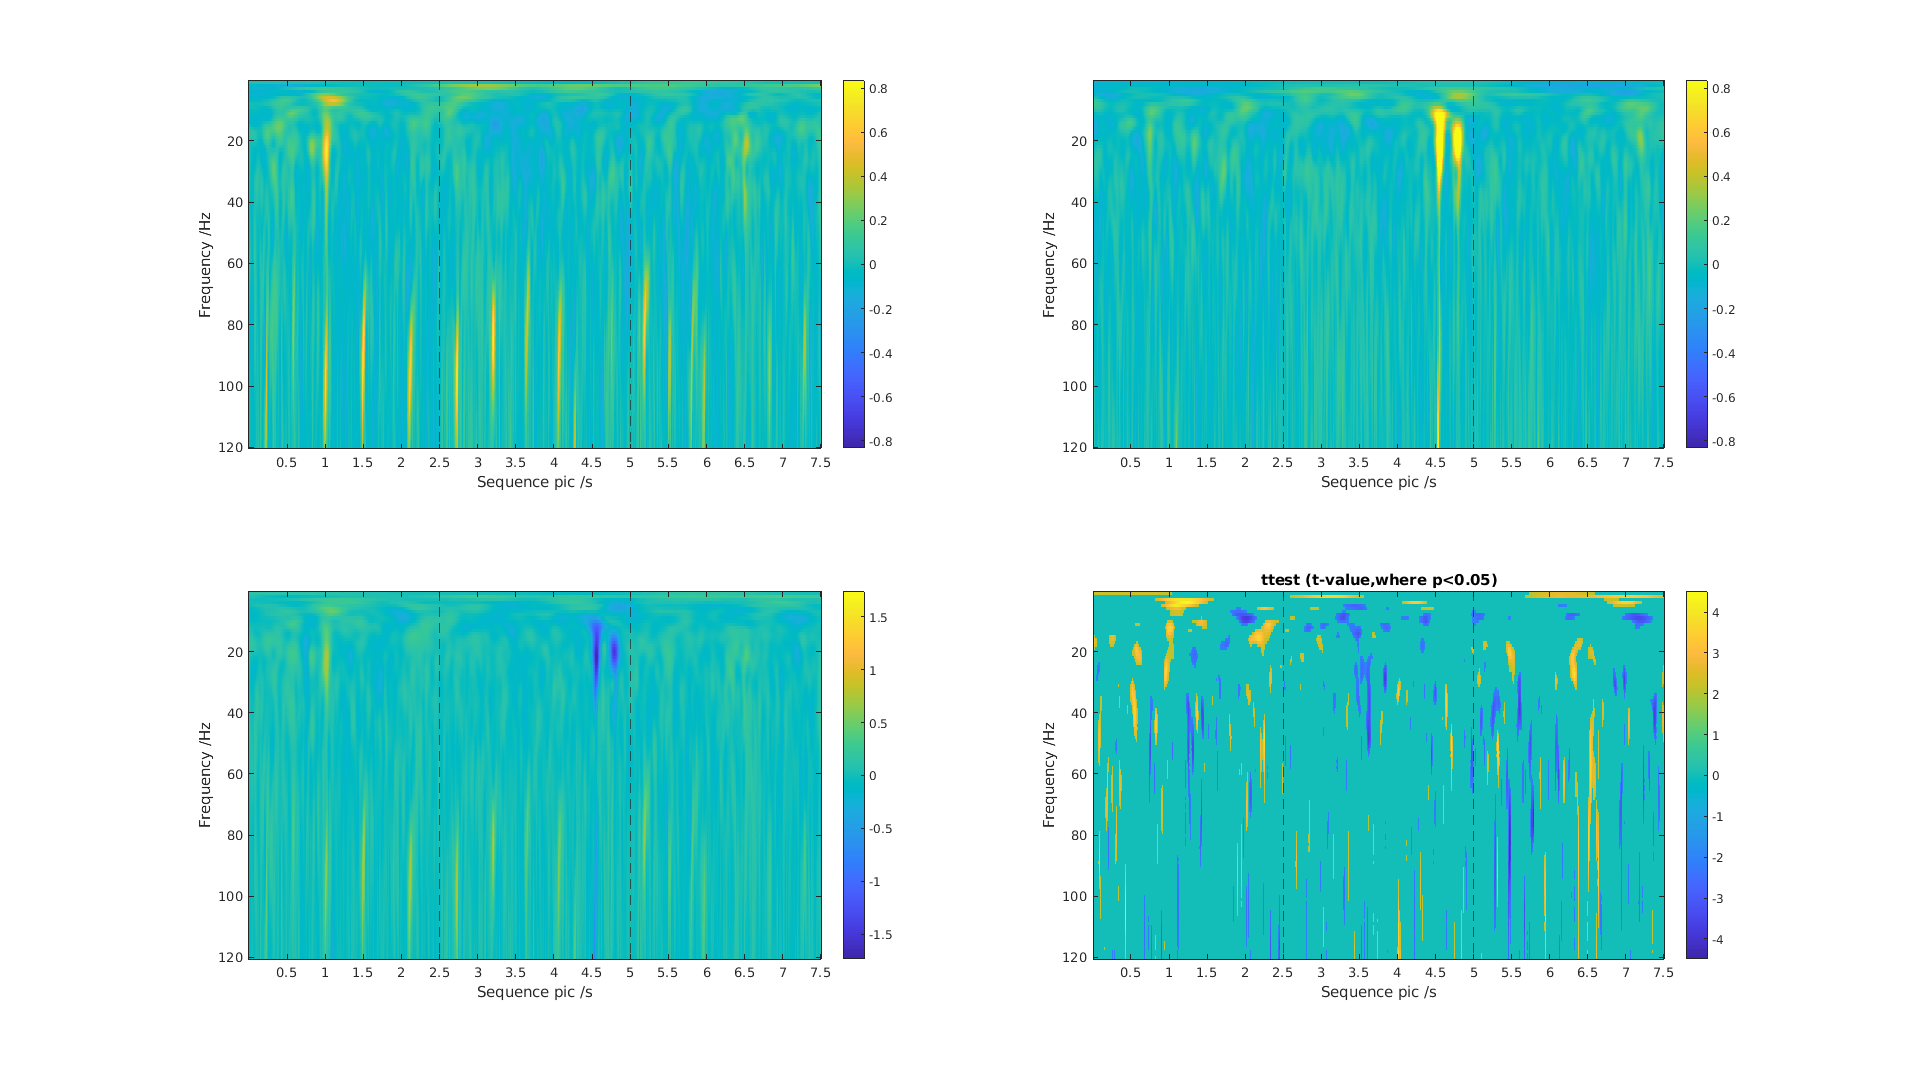

plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet') 

cp = 1×197 cell array
    {3587×1 double}    {2831×1 double}    {2123×1 double}    {1572×1 double}    {835×1 double}    {693×1 double}    {499×1 double}    {584×1 double}    {559×1 double}    {566×1 double}    {526×1 double}    {551×1 double}    {457×1 double}    {457×1 double}    {437×1 double}    {315×1 double}    {417×1 double}    {376×1 double}    {363×1 double}    {328×1 double}    {369×1 double}    {367×1 double}    {288×1 double}    {334×1 double}    {332×1 double}    {321×1 double}    {309×1 double}    {285×1 double}    {291×1 double}    {333×1 double}    {279×1 double}    {290×1 double}    {277×1 double}    {263×1 double}    {248×1 double}    {252×1 double}    {249×1 double}    {230×1 double}    {241×1 double}    {244×1 double}    {252×1 double}    {212×1 double}    {195×1 double}    {196×1 double}    {196×1 double}    {199×1 double}    {203×1 double}    {220×1 double}    {219×1 double}    {190×1 double}    {189×1 double}    {180×1 double}    {182×1 double}    {140×1 double}  

pp =     0.0048    0.0132    0.0385    0.1819    0.6263    0.8380    0.8427    0.8753    0.8838    0.9171    0.9352    0.9422    0.9471    0.9658    0.9783    0.9845    0.9877    0.9877    0.9887    0.9911    0.9915    0.9943    0.9944    0.9961    0.9964    0.9965    0.9973    0.9979    0.9980    0.9982    0.9984    0.9992    0.9993    0.9995    0.9996    0.9996    0.9996    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


% manual 
group_dir = '/bigvault/Projects/seeg_pointing/results/memory_group/';
% load wavlet data for subject
data_bd = load_mat([group_dir,'wavelet/wavele_manual_1.mat']);
data_non_bd = load_mat([group_dir,'wavelet/wavele_manual_2.mat']);

data_bd = data_normalized_bd;
data_non_bd = data_normalized_non_bd;


% condition
temp = squeeze(mean(data_bd(:,:,:,:),1));
bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd(:,:,:,:),1)); 
non_bd = permute(temp,[2,3,1]);

% position
temp = squeeze(mean(data_bd([7,13],:,:,:),1));
wavelet_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_bd([6,12],:,:,:),1)); 
wavelet_pre_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([7,13],:,:,:),1)); 
wavelet_non_bd = permute(temp,[2,3,1]);

temp  = squeeze(mean(data_non_bd([6,12],:,:,:),1)); 
wavelet_pre_non_bd = permute(temp,[2,3,1]);

[cp, pp, ~, ~]= plt_rsa_sd_perm(bd,non_bd,'wavelet')

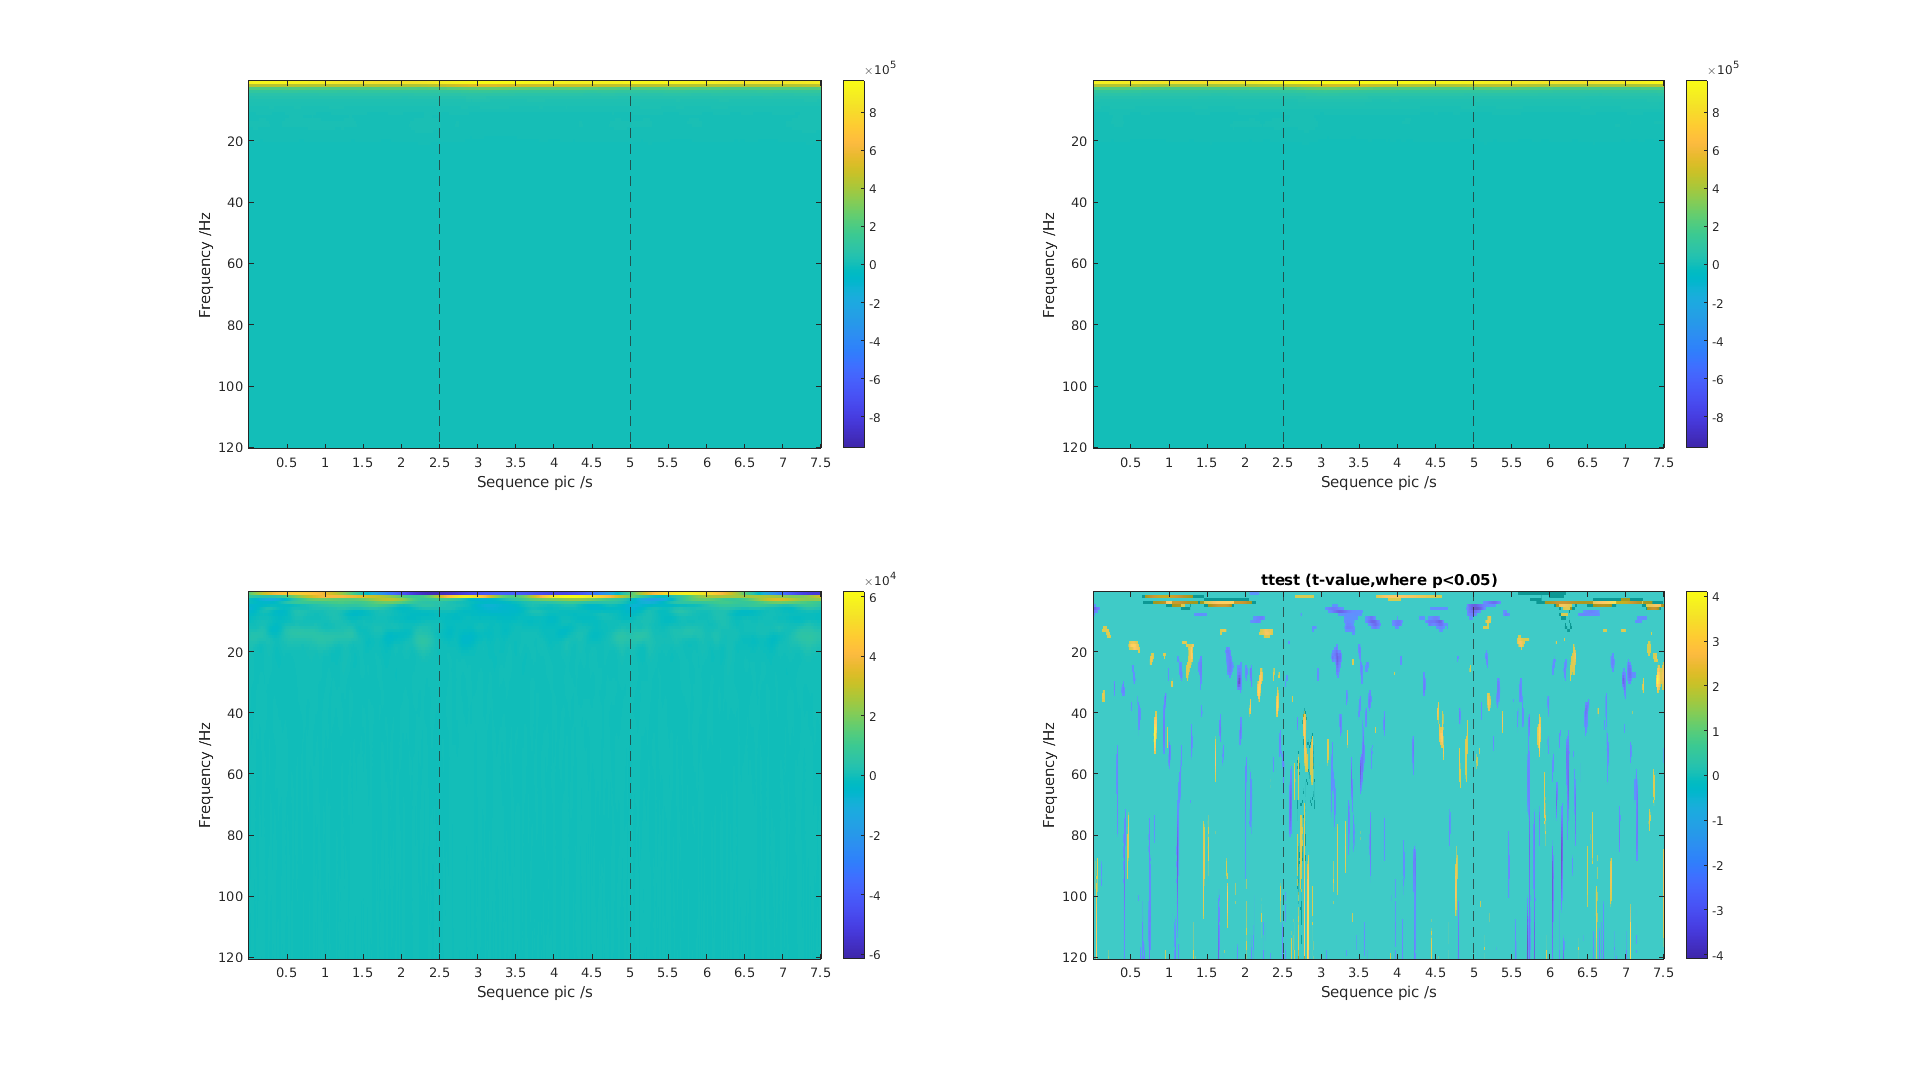

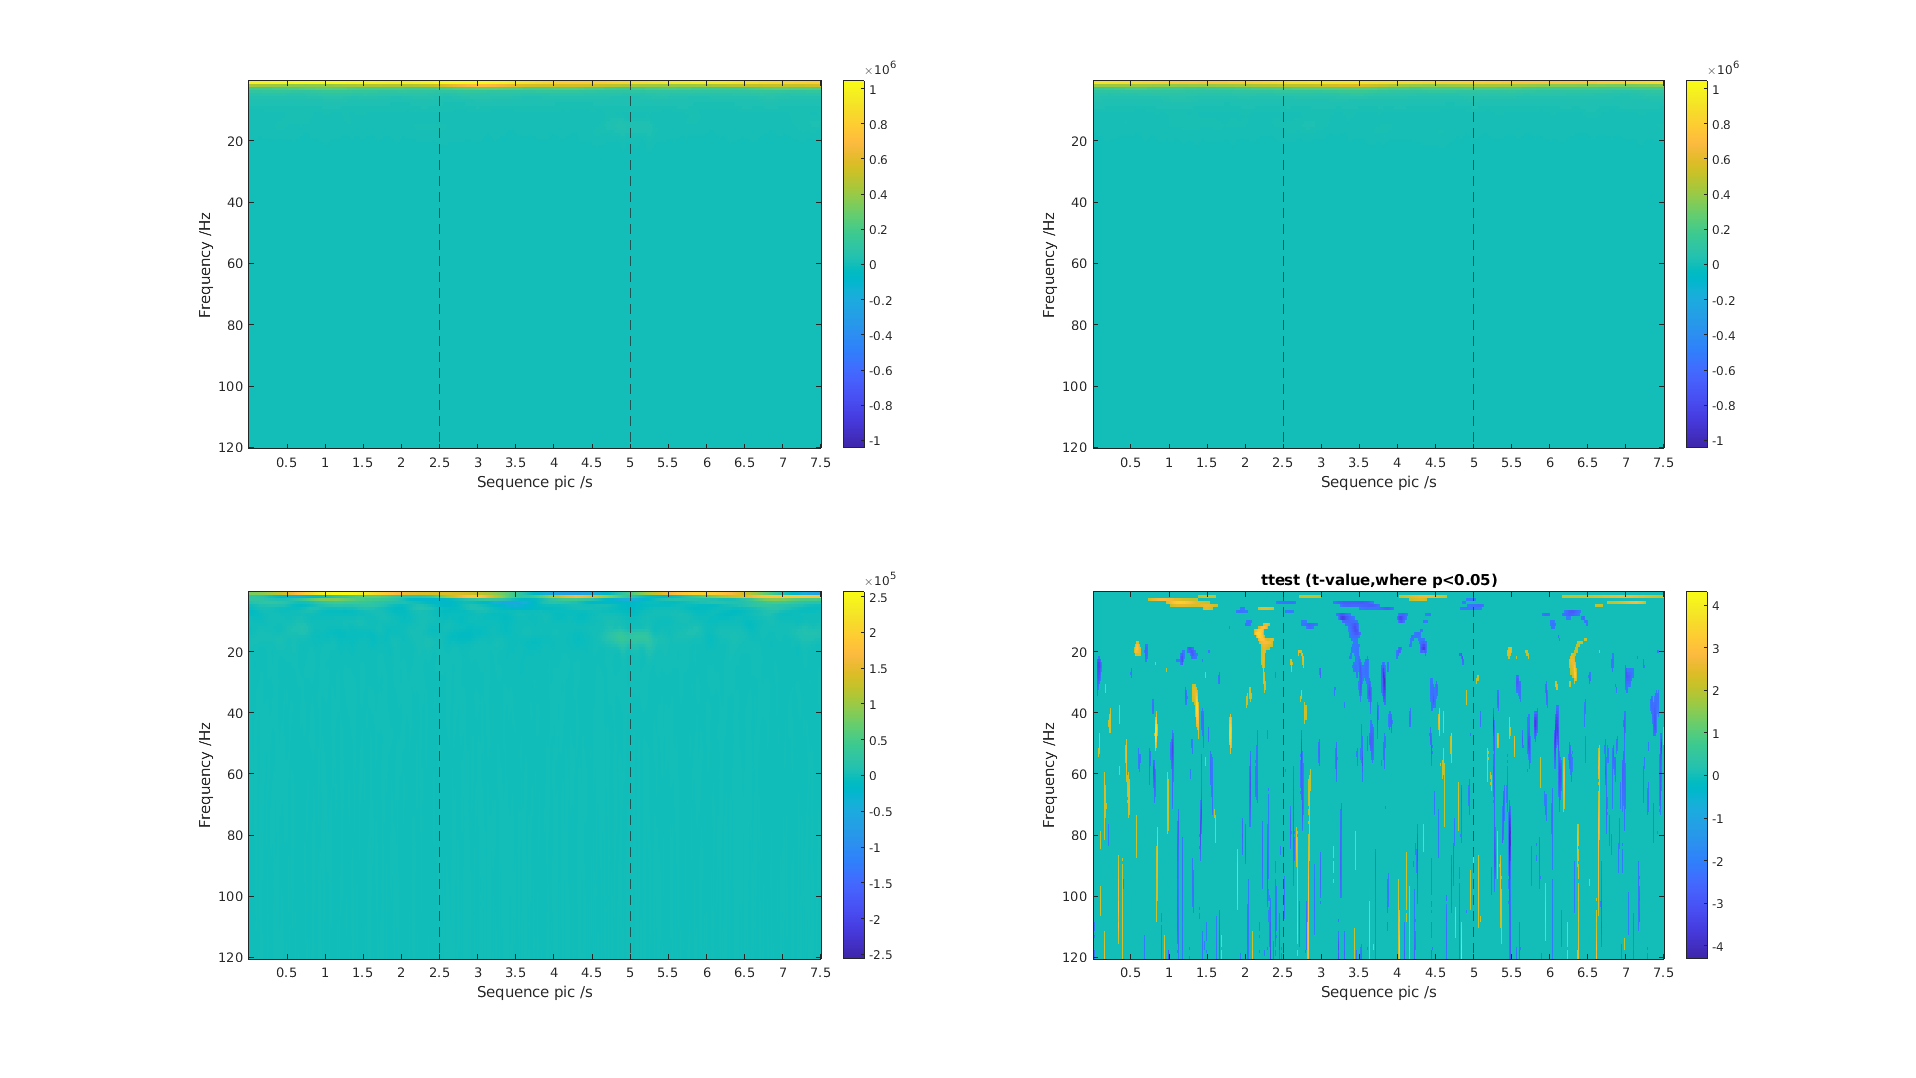

sgtitle('manual remove epilepsy(conidtion)')

[cp, pp, ~, ~]= plt_rsa_sd_perm(wavelet_bd,wavelet_non_bd,'wavelet')

sgtitle('manual remove epilepsy(position)')

#### 2 turns

% zoom in 1-25Hz
subject='subject1-27 (2turn)'

subject = 'subject1-27 (2turn)'

data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;

Unable to resolve the name wavelet_subject.subjects.

for subi=1:length(subjects)
    for seqi=1:6
    data_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),seqi+6:6:18)),3);
    data_non_bd{subi,seqi} = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),seqi+6:6:18)),3);
    end
end
plt_wavelet_sd(data_bd, data_non_bd, subject, plot_window)    

## Theta (permutation)

freq = 1:20;
data1 = wavelet_bd(freq,:,:);
data2 = wavelet_non_bd(freq,:,:);
[cp, pp, ~, ~]= plt_rsa_sd_perm(data1,data2,'wavelet');

% linear mixed model
sub = data_epoch.info.sub_id;
sub_ids = [sub;sub];
chan_id = [1:57,1:57]';
condition = [ones(57,1);zeros(57,1)];
result_lme=zeros([size(data1,[1,2]),3]);
for i= 1:size(data1,1)
    disp(i)
    result_temp=zeros([size(data1,2),3]);
    parfor j= 1:size(data1,2)
        data = [squeeze(data1(i,j,:));squeeze(data2(i,j,:))];
        tbl = table(data,sub_ids,chan_id,condition,'VariableNames',{'wavelet','subject','channel','condition'});
        lme = fitlme(tbl,'wavelet~condition+(condition|subject)+(condition|channel)');
        temp = dataset2table(lme.Coefficients);
        result_temp(j,:)=[temp.Estimate(2),temp.tStat(2),temp.pValue(2)];
        if j/500==0
            disp(j)
        end
    end
    result_lme(i,:,:) =result_temp; 
end

figure;plt_imagesc((result_lme(:,:,3)<0.05).*result_lme(:,:,2),'wavelet_s')
title('lme')

% mask
i=1;
mask = NaN(size(data1(freq,:,1)));
mask(cp{1, i}) = 1;
figure;plt_imagesc(mask,'wavelet')
title(['wavelet Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(pp(i)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% data in the mask
res_bd =[];
res_non_bd =[];
for chani = 1:size(data1,3)

    res_bd = nanmean(squeeze(data1(:,:,chani)).*mask,[1,2]);
    res_non_bd = nanmean(squeeze(data2(:,:,chani)).*mask,[1,2]);

    result(chani,:) = [res_bd;res_non_bd];
end
figure
plt_box_line(result,{'bd','on bd'})
title(['cluster',num2str(i)])
sum(result(:,1)>result(:,2))

% linear mixed-effects model for each pixel(control group effect)
sub = data_epoch.info.sub_id;
sub_ids = [sub;sub];
chan_id = [1:57,1:57]';
condition = [ones(57,1);zeros(57,1)];
result_lme=zeros([size(data1,[1,2]),3]);
for i= 1:size(data1,1)
    disp(i)
    result_temp=zeros([size(data1,2),3]);
    parfor j= 1:size(data1,2)
        data = [squeeze(data1(i,j,:));squeeze(data2(i,j,:))];
        tbl = table(data,sub_ids,chan_id,condition,'VariableNames',{'wavelet','subject','channel','condition'});
        lme = fitlme(tbl,'wavelet~condition+(condition|subject)+(condition|channel)');
        temp = dataset2table(lme.Coefficients);
        result_temp(j,:)=[temp.Estimate(2),temp.tStat(2),temp.pValue(2)];
        if j/500==0
            disp(j)
        end
    end
    result_lme(i,:,:) =result_temp;
end
figure;plt_imagesc((result_lme(:,:,3)<0.05).*result_lme(:,:,2),'wavelet_s')
title('lme')
figure;plt_imagesc(result_lme(:,:,1),'wavelet_s')

## Theta (anova)

wavelet = cat(3, wavelet_bd,wavelet_pre_bd,wavelet_non_bd,wavelet_pre_non_bd);
condition  = reshape(repmat([1,1,2,2], 10, 1),[],1);
position  = reshape(repmat([1,2,1,2], 10, 1),[],1);
p2=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p2(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

% ttest
data_bd = [];
data_non_bd = [];
subjects =wavelet_subject.subjects;
for subi=1:length(subjects)
    wavelet_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_bd(subjects(subi),[7,13])),3);
    wavelet_non_bd(:,:,subi) = mean(cell2matrix(wavelet_subject.data_non_bd(subjects(subi),[7,13])),3);
end

figure
subplot(1,2,1)
imagesc(mean(wavelet_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
subplot(1,2,2)
imagesc(mean(wavelet_non_bd,3))
caxis([-0.4,0.4])
yticks(0:20:120);
        yticklabels([0:20:120]);
        ylabel('Frequency /Hz');
        xticks(0:256:7.5*512);
        xticklabels([0:256:7.5*512]/512);
        xlabel('Sequence pic /s')
        xline(2.5*512,'--')
        xline(5*512,'--')
        colorbar()
colorbar()
plt_rsa_sd(wavelet_bd,wavelet_non_bd,'wavelet')

% mask combain  and anova
p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(1)}) = 1;
figure;imagesc(mask)
title('mask(anovan)')
mask_anova2 = mask;

p=p2;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:3
    subplot(2,2,i)
    if i<4
        imagesc(a(:,:,i))
        title(['anovan: ',anovan_name{i}])
    else
        imagesc(pic_corr_h)
        title('Mask')
    end
    yticks(0:20:120);
    yticklabels([0:20:120]);
    ylabel('Object pic /s')
    xticks(0:256:7.5*512);
    xticklabels([0:256:7.5*512]/512);
    xlabel('Sequence pic /s')
    xline(2.5*512,'--')
    xline(5*512,'--')
    colorbar()
end
set(gcf, 'Position', [1 25 1920 1080]);

% plot anova result condition(anova 2*2, mask ttest)
mask_anova=mask_anova2;
data = [];
data(1,1,:) = squeeze(mean(mean(wavelet_bd.*mask_anova,1),2));
data(1,2,:) = squeeze(mean(mean(wavelet_pre_bd.*mask_anova,1),2));
data(2,1,:) = squeeze(mean(mean(wavelet_non_bd.*mask_anova,1),2));
data(2,2,:) = squeeze(mean(mean(wavelet_pre_non_bd.*mask_anova,1),2));

figure
clim = [-0.5,0.5];
subplot(2,3,1)
temp = wavelet_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,2)
temp = wavelet_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,3)
temp = wavelet_pre_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,4)
temp = wavelet_pre_non_bd.*mask_anova;
imagesc(mean(temp(1:14,1490:1810),3))
title('pre non Boundary in mask')
caxis(clim)
colorbar()
subplot(2,3,5)
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')
subplot(2,3,6)
imagesc(mask_anova)
title('Mask')
yticks(0:20:120);
yticklabels([0:20:120]);
ylabel('Object pic /s')
xticks(0:256:7.5*512);
xticklabels([0:256:7.5*512]/512);
xlabel('Sequence pic /s')
xline(2.5*512,'--')
xline(5*512,'--')
colorbar()
sgtitle('obj2seq mask')

% permutest all 18 picture


% permutation only 1000 times
tic
[clusters_perm, p_perm, t_sums_perm, permutation_distribution ] = permutest(wavelet_bd,wavelet_non_bd,true,0.05,1000);
toc


% permutest p=0.05
i=1;
mask = NaN(size(data_bd(:,:,1)));
mask(clusters_perm{1, i}) = 1;
figure;plt_imagesc(mask,'wavelet')
title(['wavelet Boundary and non Boundary Cluster-based Permutation  (largest cluster, p =',num2str(p_perm(i)),')'])
set(gcf, 'Position', [1 25 1920 1080]);

% anova   position(2,[boundary, non_boundary])*position(6,[1:6])
wavelet=[];
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])));
end
for pici =1:6
wavelet = cat(3, wavelet,cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])));
end
condition  = reshape(repmat([1,2], 10*6, 1),[],1);
position  = reshape(repmat([1:6,1:6], 10, 1),[],1);
p6=[];
for i = 1:size(wavelet,1)
    for j=1:size(wavelet,2)
        p6(i,j,:) = anovan(squeeze(wavelet(i,j,:)),{condition position},'model','interaction','varnames',{'condition','position'},'display','off');
    end
end

% compare anova mask in 2*2 and 2*6
p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anova_condition = a(:,:,1);
BW_anova = bwperim(mask_anova2);
CC = bwconncomp(anova_condition);
cc_size=[];
for i=1:length(CC.PixelIdxList)
    cc_size(i)=length(CC.PixelIdxList{1, i});
end
[cc_sort,cc_idx] = sort(cc_size,'descend');
mask = zeros(size(anova_condition));
mask(CC.PixelIdxList{1, cc_idx(6)}) = 1;
figure;imagesc(max(mask,BW_anova*2))
title('mask(anovan)')
mask_anova6 = mask;

p=p6;
a = p; a(a<0.05)=-1; a(a>=0.05)=0; a=abs(a);
anovan_name = {'condition','position','condition*position'};
figure
for i= 1:4
    subplot(2,2,i)
    if i<4
          plt_imagesc(max(a(:,:,i),BW_anova*2),'wavelet');
          title(['anovan: ',anovan_name{i}])
    else
        plt_imagesc(max(mask_anova6,BW_anova*2),'wavelet');
        title('mask(anovan)')
    end
end
set(gcf, 'Position', [1 25 1920 1080]);

% plot anova result condition(anova 2*6, mask ttest)
data = [];
for pici=1:6
    data(1,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
    data(2,pici,:) = squeeze(mean(mean(cell2matrix(wavelet_subject.data_non_bd(:,[pici,pici+6,pici+12])).*mask_anova6,1),2));
end
figure
plt_bar_group(data,{'Boundary','non Boundary'}) % no ttest for each bins
title('meann in mask(ttest) position(2)*position(6)')
